close("all"); clear; clc;
setmadsympath();

## Sharp model parameters

Cdelta = 12.6738;
Cf1 = 11174;
Cf2 = 938.6;
Cr1 = 15831;
Cr2 = 1325.6;
Ibxx = 31.18;
Ibxz = -1.7355;
Ibzz = 21.07;
Ihxx = 1.2338;
Ihzz = 0.442;
a = 0.9485376;
af0 = 0.02;
an = 0.1158;
ar0 = 0.02;
b = 0.4798;
e = 0.0244;
f = 0.0283;
g = 9.80665;
h = 0.6157;
ify = 0.7186;
iry = 1.0508;
mb = 217.45;
mh = 30.65;
rf = 0.3048;
rr = 0.3048;
tf = 0.05;
tr = 0.05;
caster = 0.4715;

## Normal forces

Zr = 1.428E03;
Zf = 1.005E03;

## Tire coefficients

Longitudinal :

kkf = 20;
kkr = 20;

Lateral :

kaf = Cf1/Zf;
klf = Cf2/Zf;
kar = Cr1/Zr;
klr = Cr2/Zr;

## Longitudinal displacement

p = b + (a - an)/cos(caster);
fw0 = (0.0085 + 0.018/p);
fw2 = 1.59E-06/p;

## Pryde parameters

params = @(v)[
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    af0;
    an;
    ar0;
    b;
    e;
    f;
    fw0;
    fw2;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    mb;
    mh;
    rf - tf;
    rr - tr;
    tf;
    tr;
    caster
    ];

## Model

nv = 1000;
vx = linspace(50,130,nv)./3.6;
plant = @prydeMotorcycleLateralStateSpace;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

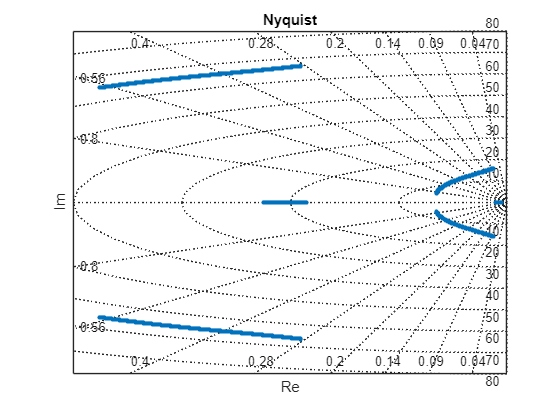

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

## BikeSim results

vx = num2str(80);
dpath = "G:\My Drive\BikeSimResults\BigSports\";
spath = "OpenLoop" + vx + "kph\";
fname = "results_big_sports_open_loop_";
load(dpath + spath + fname + vx + "kph.mat");

time = results.Time;
camber = deg2rad(results.Roll);
steer = deg2rad(results.Steer);
wz = deg2rad(results.AVz);
vy = results.VyW0_2./3.6;
wx = deg2rad(results.AVx);
ws = deg2rad(results.M_StrSys./0.2212);

x_mes = [camber,steer,wz,vy,wx,ws];

Mz = results.M_Str_In;

## Model results

sys80 = plant(params(80));
x_sys80 = lsim(sys80,[0.*Mz,Mz],time);

## State observer

L = standardLMI(sys80.A,sys80.C,0.001);


 num. of constraints = 42
 dim. of sdp    var  = 18,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e+04|2.8e+00|2.9e+08| 5.999994e+07  0.000000e+00| 0:0:00| chol  1  1 
 1|0.989|1.000|1.0e+03|1.7e-07|2.3e+07| 2.153505e+07  0.000000e+00| 0:0:00| chol  1  1 
 2|0.989|1.000|1.1e+01|1.7e-08|2.6e+05| 2.370854e+05  0.000000e+00| 0:0:00| chol  1  1 
 3|0.989|1.000|1.2e-01|1.7e-09|2.8e+03| 2.610010e+03  0.000000e+00| 0:0:00| chol  1  1 
 4|0.989|1.000|1.4e-03|1.7e-10|3.1e+01| 2.873225e+01  0.000000e+00| 0:0:00| chol  1  1 
 5|0.989|1.000|1.5e-05|1.7e-06|3.4e-01| 3.162916e-01  0.000000e+00| 0:

A = sys80.A - L*sys80.C;
syso = ss(A,sys80.B,sys80.C,0);
x_est = lsim(syso,[0.*Mz,Mz],time);

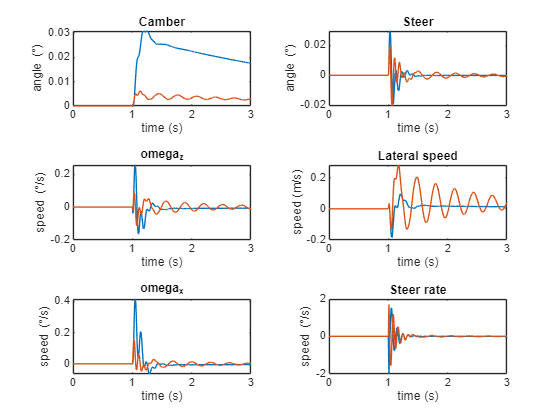

fig = figure();
tl = tiledlayout(3,2,"Parent",fig);

titles = [
    "Camber";
    "Steer";
    "omega_z";
    "Lateral speed";
    "omega_x";
    "Steer rate"
    ];

units = [
    "angle (\circ)";
    "angle (\circ)";
    "speed (\circ/s)";
    "speed (m/s)";
    "speed (\circ/s)";
    "speed (\circ/s)"
    ];

for k = 1:6
    axe = nexttile(k);
    hold(axe,"on");
    plot(axe,time,x_mes(:,k));
    plot(axe,time,x_sys80(:,k));
    hold(axe,"off");
    box(axe,"on");
    title(axe,titles(k));
    xlabel(axe,"time (s)");
    ylabel(axe,units(k));
end

function L = standardLMI(A,C,gm)
    arguments
        A (6,6) double;
        C (6,6) double;
        gm (1,1) double;
    end
    yalmip('clear');
    opts = sdpsettings('solver','sdpt3');
    I = eye(size(A));
    P = sdpvar(6,6);
    R = sdpvar(6,6);
    g = 1/(gm^2);

    lmiA = P >= 0;
    lmiB = [
        A.'*P + P*A - R.'*C - C.'*R + I, P;
        P, -g.*I
        ] <= 0;

    cons = [
        lmiA;
        lmiB
        ];

    optimize(cons,0,opts);

    L = value(P)\value(R.');
end